close all
clear variables

#### 1. Импорт данных

data = readmatrix("data.txt")

data = 	1.0e+03 *

    0.0181    0.0182    0.0183    0.0184    0.0185    0.0186    0.0187    0.0188    0.0189    0.0190    0.0191    0.0192    0.0193    0.0194    0.0195
         0    0.0920    0.1870    0.2890    0.3980    0.5130    0.6380    0.7660    0.9040    1.0490    1.2020    1.3620    1.5380    1.7230    1.9140
         0    0.1080    0.2240    0.3480    0.4810    0.6190    0.7720    0.9350    1.1120    1.2940    1.4880    1.7010    1.9270    2.1570    2.3890
         0    0.1350    0.2740    0.4210    0.5760    0.7410    0.9130    1.0940    1.2850    1.4830    1.6930    1.9090    2.1350    2.3710    2.6190



OY = data(1, :)';

OX1 = data(2, :)';
OX2 = data(3, :)';
OX3 = data(4, :)';

p1= polyfit(OX1, OY, 3);
p2= polyfit(OX2, OY, 3);
p3= polyfit(OX3, OY, 3);

f1 = polyval(p1, OX1);
f2 = polyval(p2, OX2);
f3 = polyval(p3, OX3);

names = ["Пустй калориметр"; "Алюминий"; "Латунь"];

for indx = 1:14
    OY1(indx) = (OY(indx + 1) - OY(indx)) / (OX1(indx + 1) - OX1(indx));
end

for indx = 1:14
    OY2(indx) = (OY(indx + 1) - OY(indx)) / (OX2(indx + 1) - OX2(indx));
end

for indx = 1:14
    OY3(indx) = (OY(indx + 1) - OY(indx)) / (OX3(indx + 1) - OX3(indx));
end

Y     = OY;
Y(15) = [];


p11 = polyfit(Y, OY1', 3);
p21 = polyfit(Y, OY2', 3);
p31 = polyfit(Y, OY3', 3);

f11 = polyval(p11, Y);
f21 = polyval(p21, Y);
f31 = polyval(p31, Y);









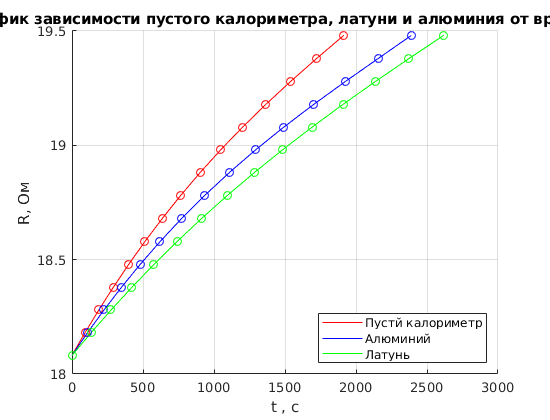

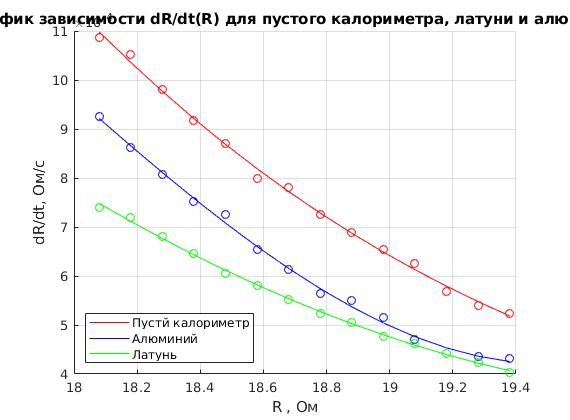

%{
x=[22.0 24.0 27.0 30.0 31.0 35.0 40.0];
y=[1.24 1.37 1.46 1.26 1.66 1.84 1.99];
% Найдем коэффициэнты полинома
a=polyfit(x,y,5),
%  Найдем значения полиномов в интервале от 20 до 40
x1=20:0.5:40;
y1=polyval(a,x1);
y0 = polyval(a,x); % расчет ф-ции в точках данных
% Погрешность аппроксимации по МНК
e=sum((y0-y).^2)/length(y)
%}



graph_1 = figure;
hold on;
    plot(OX1,  f1, 'r-');
    plot(OX2,  f2, 'b-');
    plot(OX3,  f3, 'g-');
    plot(OX1,  OY , 'ro');
    plot(OX2,  OY , 'bo');
    plot(OX3,  OY , 'go');
hold off;

set   (graph_1, 'Visible', 'on'); 
ylabel('R, Ом');
xlabel('t , c');
title ('График зависимости пустого калориметра, латуни и алюминия от времени');
legend(names, 'Location','southeast');
grid on; 

graph_2 = figure;
hold on;
    plot(Y,  f11, 'r-');
    plot(Y,  f21, 'b-');
    plot(Y,  f31, 'g-');
    plot(Y,  OY1, 'ro');
    plot(Y,  OY2, 'bo');
    plot(Y,  OY3, 'go');
hold off;
set   (graph_2, 'Visible', 'on'); 
ylabel('dR/dt, Ом/c');
xlabel('R , Ом');
title ('График зависимости dR/dt(R) для пустого калориметра, латуни и алюминия');
legend(names, 'Location','southwest');
grid on; 

saveas(graph_1, './images/graph_1.png');
saveas(graph_2, './images/graph_2.png');

#### 6. Построение графика спектров всех звёзд

%graphStars = figure;

%hold on;
%for indxGraph = 1 : numStars
%    if speed(indxGraph) > 0
%        plot(lambda, spectra(:, indxGraph), ...
%             '-', ...
%             'Linewidth', 3);
%    else 
%        plot(lambda, spectra(:, indxGraph), ...
%             '--', ...
%             'Linewidth', 1); 
%    end
%end
%hold off;

#### 7. Добавление на график названия, подписи осей, сетки и легенды

%set   (graphStars, 'Visible', 'on'); 
%xlabel('Длина волны, нм');
%ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
%title ('Спектры звёзд');
%legend(starNames);
%grid on;
%saveas(graphStars, 'spectra.png');